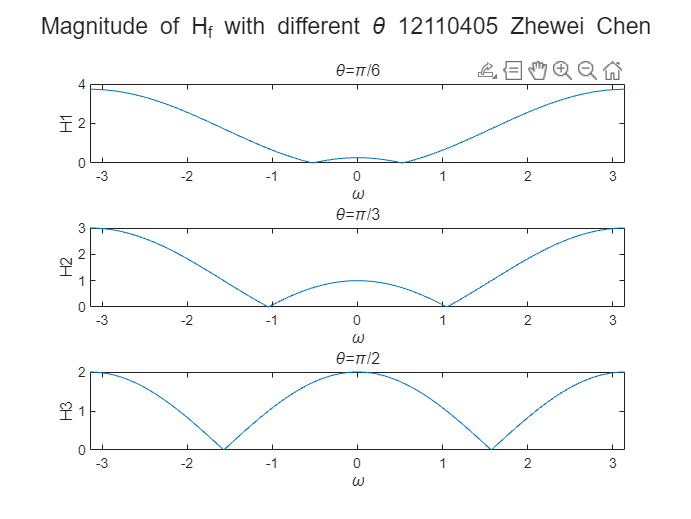

clc;clear;close all;
w=-pi:0.01:pi;
z=exp(1i*w);
H1=1-2*cos(pi/6)*z.^(-1)+z.^(-2);
H2=1-2*cos(pi/3)*z.^(-1)+z.^(-2);
H3=1-2*cos(pi/2)*z.^(-1)+z.^(-2);

figure;
sgtitle('Magnitude of H_f with different \theta 12110405 Zhewei Chen');
subplot(311);
plot(w,abs(H1));
title('\theta=\pi/6');xlabel('\omega');ylabel('H1');xlim([-pi,pi])
subplot(312)
plot(w,abs(H2));
title('\theta=\pi/3');xlabel('\omega');ylabel('H2');xlim([-pi,pi])
subplot(313)
plot(w,abs(H3));
title('\theta=\pi/2');xlabel('\omega');ylabel('H3');xlim([-pi,pi])

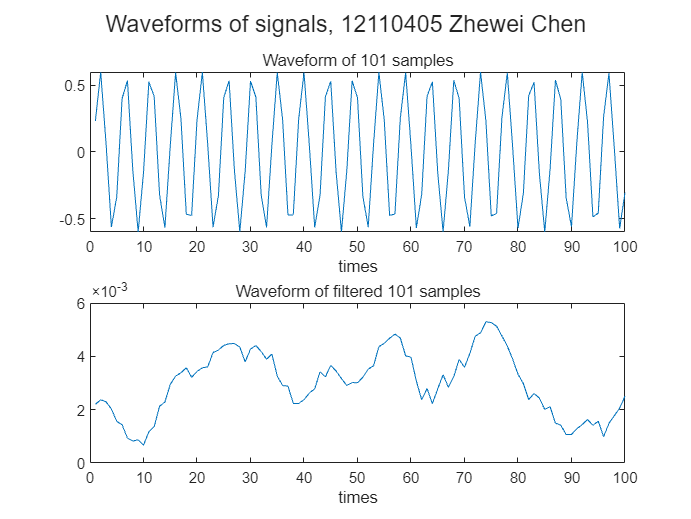

load nspeech1.mat;
 % sound(nspeech1);
 filtered_nspeech1=FIRfilter(nspeech1);
 % sound(filtered_nspeech1)

figure;
sgtitle('Waveforms of signals, 12110405 Zhewei Chen')
subplot(211)
plot(nspeech1(100:200));xlabel('times');title('Waveform of 101 samples'),xlim([0,100])
subplot(212)
plot(filtered_nspeech1(100:200));xlabel('times');title('Waveform of filtered 101 samples'),xlim([0,100])

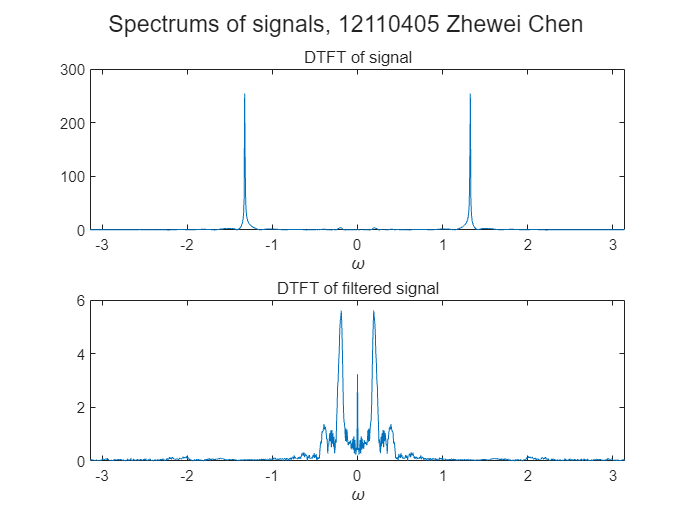


[X1,w1]=DTFT(nspeech1(100:1100),1001);
[X2,w2]=DTFT(filtered_nspeech1(100:1100),1001);

figure;
sgtitle('Spectrums of signals, 12110405 Zhewei Chen')
subplot(211);
plot(w1,abs(X1));xlabel('\omega');title('DTFT of signal'),xlim([-pi,pi])
subplot(212)
plot(w2,abs(X2));xlabel('\omega');title('DTFT of filtered signal');xlim([-pi,pi])

sound(filtered_nspeech1);